# HOW TO USE LABTOOLS PLOTTING FUNCTIONS 

This is a script to make students familiar to the plotting functions in Labtool. 

Remember** WE ALL NEED TO** adapt, implement and improve labtools. This is a lab effort to make sure that all our work can we reproduce by any lab member in the future. Meaning that if you created a new plotting finction PLEASE add an example here!

This script assume that you know how to go from c3d to mat. Please review the MAR bible to review those steps if you have any question on how to get data from nexus to matlab. 

**Make sue that you the path correspont to a folder with data. **

## Plotting Tme Course Individual Subject 

You need a params file for this. Once you get the data from nexus to matlab this file is outputed by the c3d2mat function

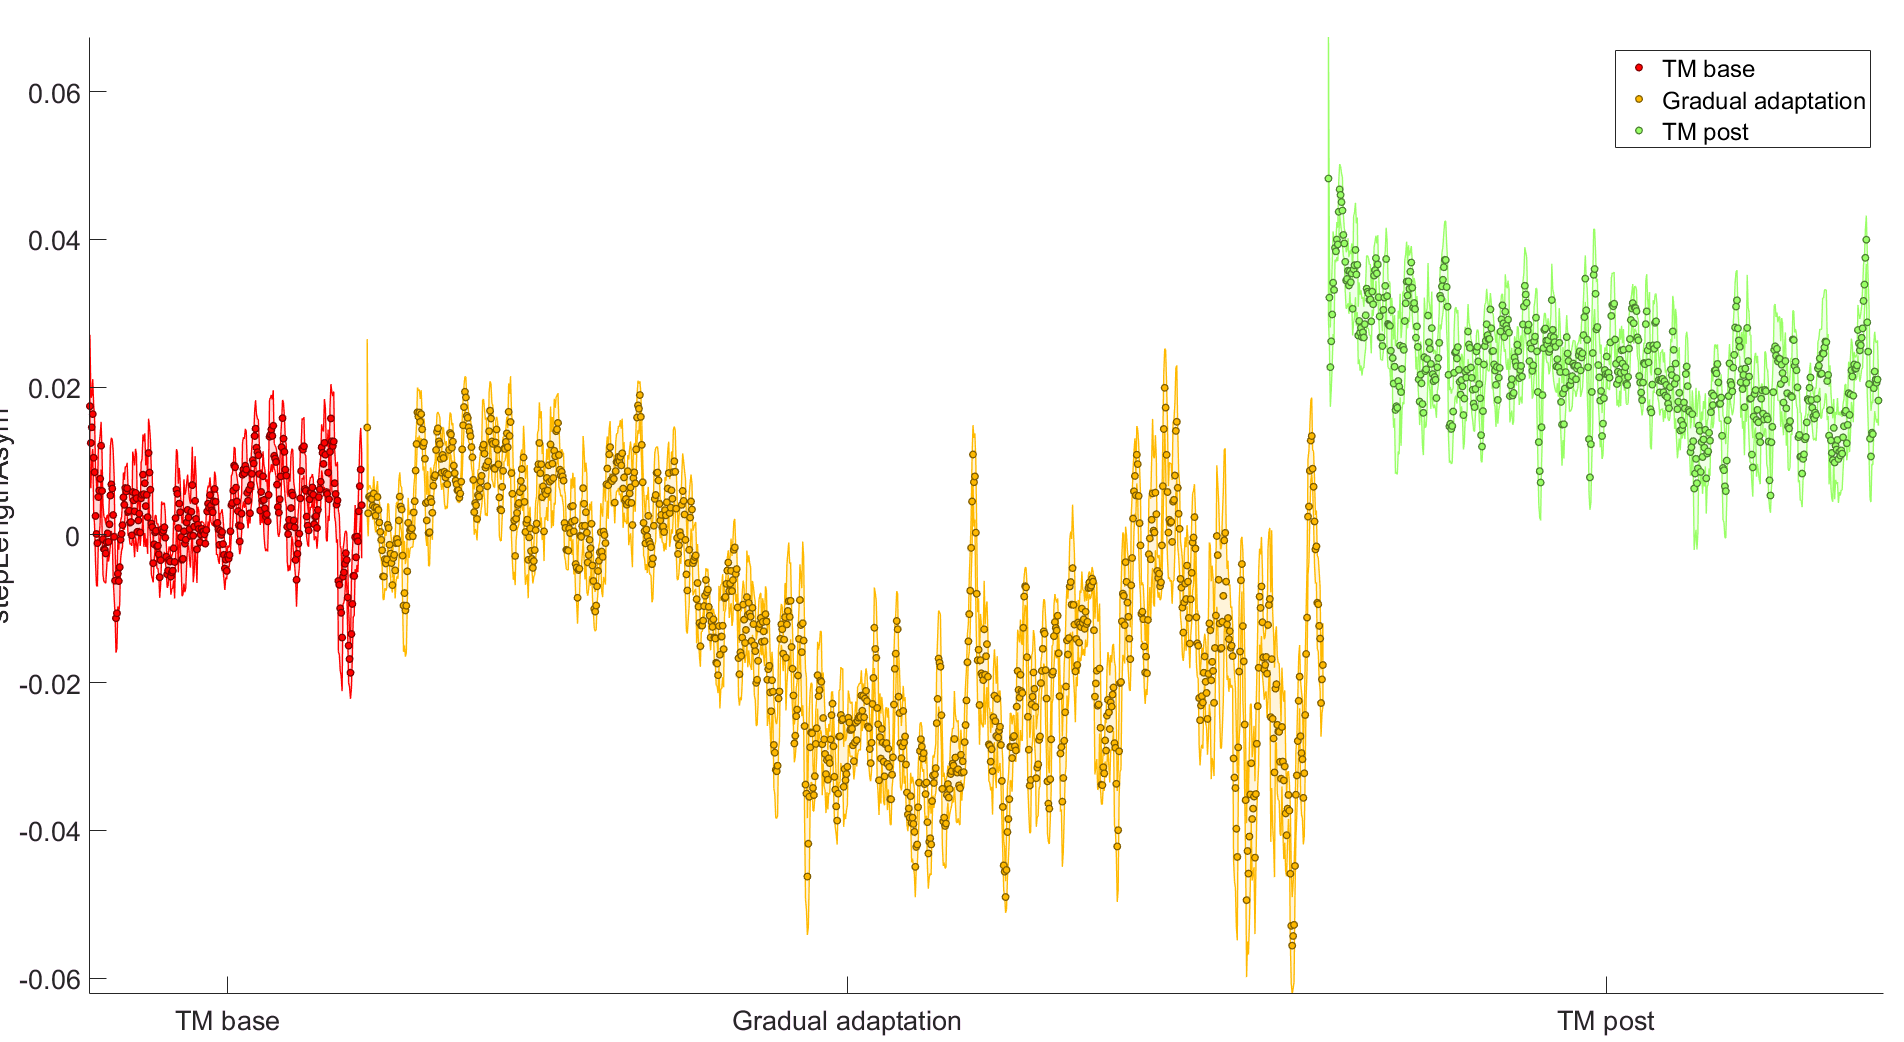

DataLocation='S:\Shared\Dulce\DistractionStudy\ParamsFiles\ParamsSubjectsForces'; %Make sure that the output of the c3d2mat function is in your current folder 
cd(DataLocation)

files=what('./');
filesList=files.mat;
LocSubjectParam=find(endsWith(filesList,{'params.mat'})==1);
Subject=filesList(LocSubjectParam(1));

load(Subject{1})

%Notice that an adaptData file will be load on your woekspace
params={'stepLengthAsym'}; %you can plot which ever parameter you are interested on check into the adaptData.data for labels
conditions={'TM base',	'Adaptation','TM post'};
binwidth=5; %Window of the running average
trialMarkerFlag=0; %1 if you want to separete the time course by trial 0 to separece by condition 
indivFlag=0; %0 we are plotting one subject
indivSubs=0; %0 we are plotting one subject
colorOrder=[]; %Let the function take care of this at least you wanted in a specific set of color then by my guess and add the list here
biofeedback= 0; % At least that you are providing with biofeedback to the subject
removeBiasFlag=1; %if you want to remove bias 
labels=[]; 
filterFlag=[];
plotHandles=[];
alignEnd=0; %0 we are plotting one subject
alignIni=0; %0 we are plotting one subject
adaptationData.plotAvgTimeCourse(adaptData,params,conditions,binwidth,trialMarkerFlag,indivFlag,indivSubs,colorOrder,biofeedback,removeBiasFlag,labels,filterFlag,plotHandles,alignEnd,alignIni);

Awesome you know how to plot the time course for one person. Always check individual subejcts data you don't want crappy data (crappy data=crappy conclusion=crappy research)

## Group(s)

Now that you have more than one subject and probably more than one group lets have some fun

Recomendatation: Put all the params files for all the subjects in one folder. The .mat files are big files that you ususally don't want to copy/have everywhere and all the infor that you need from your indv subjects is within the params.mat file.

%Example of how to create a groupAdaptationData class
%See adaptationData.createGroupAdaptData

CG=adaptationData.createGroupAdaptData({'CG07params','CG08params','CG09params','CG10params'});
D=adaptationData.createGroupAdaptData({'D07params','D08params','D09params','D10params'});

adaptDataGroups{1}=CG;
adaptDataGroups{2}=D; %You can do this with as many groups you need 

## Plot Group(s) Indv Subjects Time Course

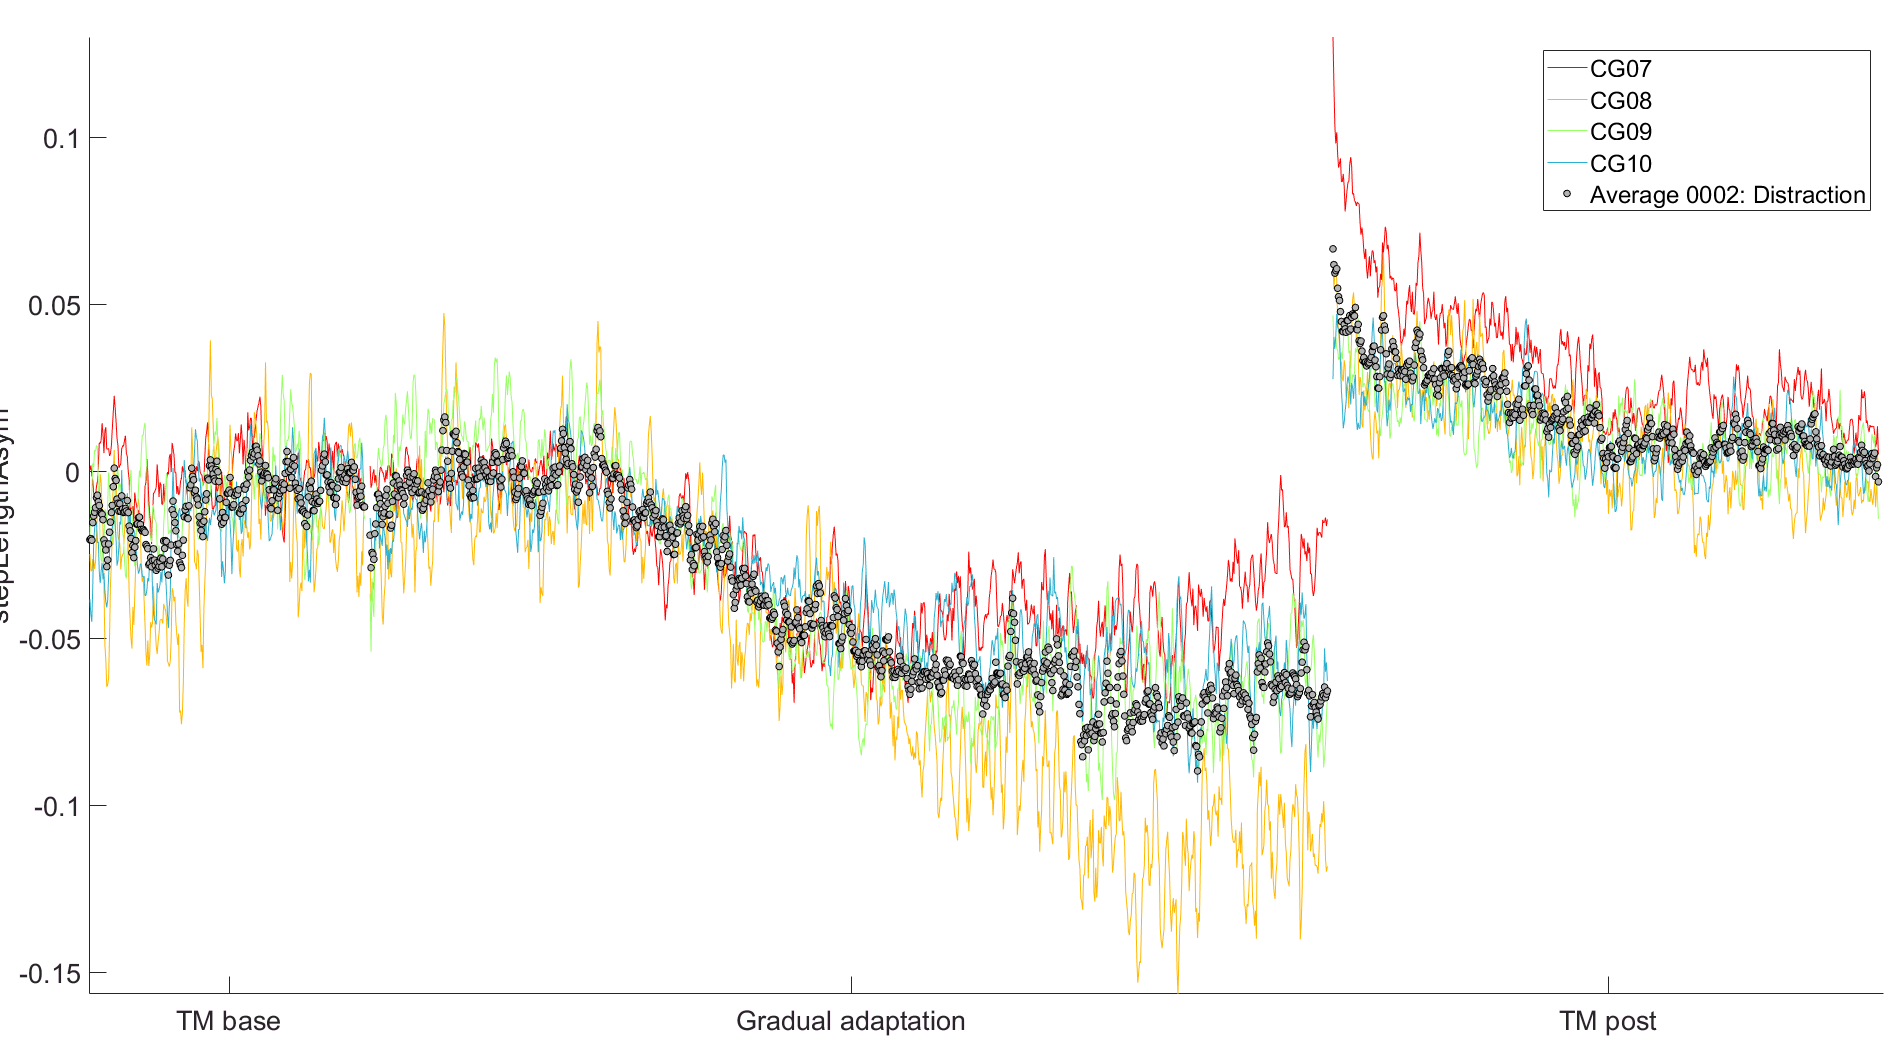

params={'stepLengthAsym'}; %you can plot which ever parameter you are interested on check into the adaptData.data for labels
conditions={'TM base',	'Adaptation','TM post'};
binwidth=5; %Window of the running average
trialMarkerFlag=0; %1 if you want to separete the time course by trial 0 to separece by condition 
indivFlag=1; %0 to plot group mean 1 to plot indiv subjects
indivSubs=[]; %Use when you want to plot a specidfic subject in a group 
colorOrder=[]; %Let the function take care of this at least you wanted in a specific set of color then by my guess and add the list here
biofeedback= 0; % At least that you are providing with biofeedback to the subject
removeBiasFlag=1; %if you want to remove bias 
labels=[]; 
filterFlag=[];
plotHandles=[];
alignEnd=0; % # strides align at the end of the trial (PLAY with it as see what happens)
alignIni=0; %  # strides align at the beginning of the trial (PLAY with it as see what happens) 

adaptData=cellfun(@(x) x.adaptData,adaptDataGroups(1),'UniformOutput',false); %Notice that adaptDataGroups(1) decide that I only want to plot the CG group 
adaptationData.plotAvgTimeCourse(adaptData,params,conditions,binwidth,trialMarkerFlag,indivFlag,indivSubs,colorOrder,biofeedback,removeBiasFlag,labels,filterFlag,plotHandles,alignEnd,alignIni);

## Plot Mean Group(s) Time Course 

Using the groupAdaptationData (see above)

The only thing that changes form the Plot Group(s) Indv Subjects Time Course section is that (indivFlag=0) 

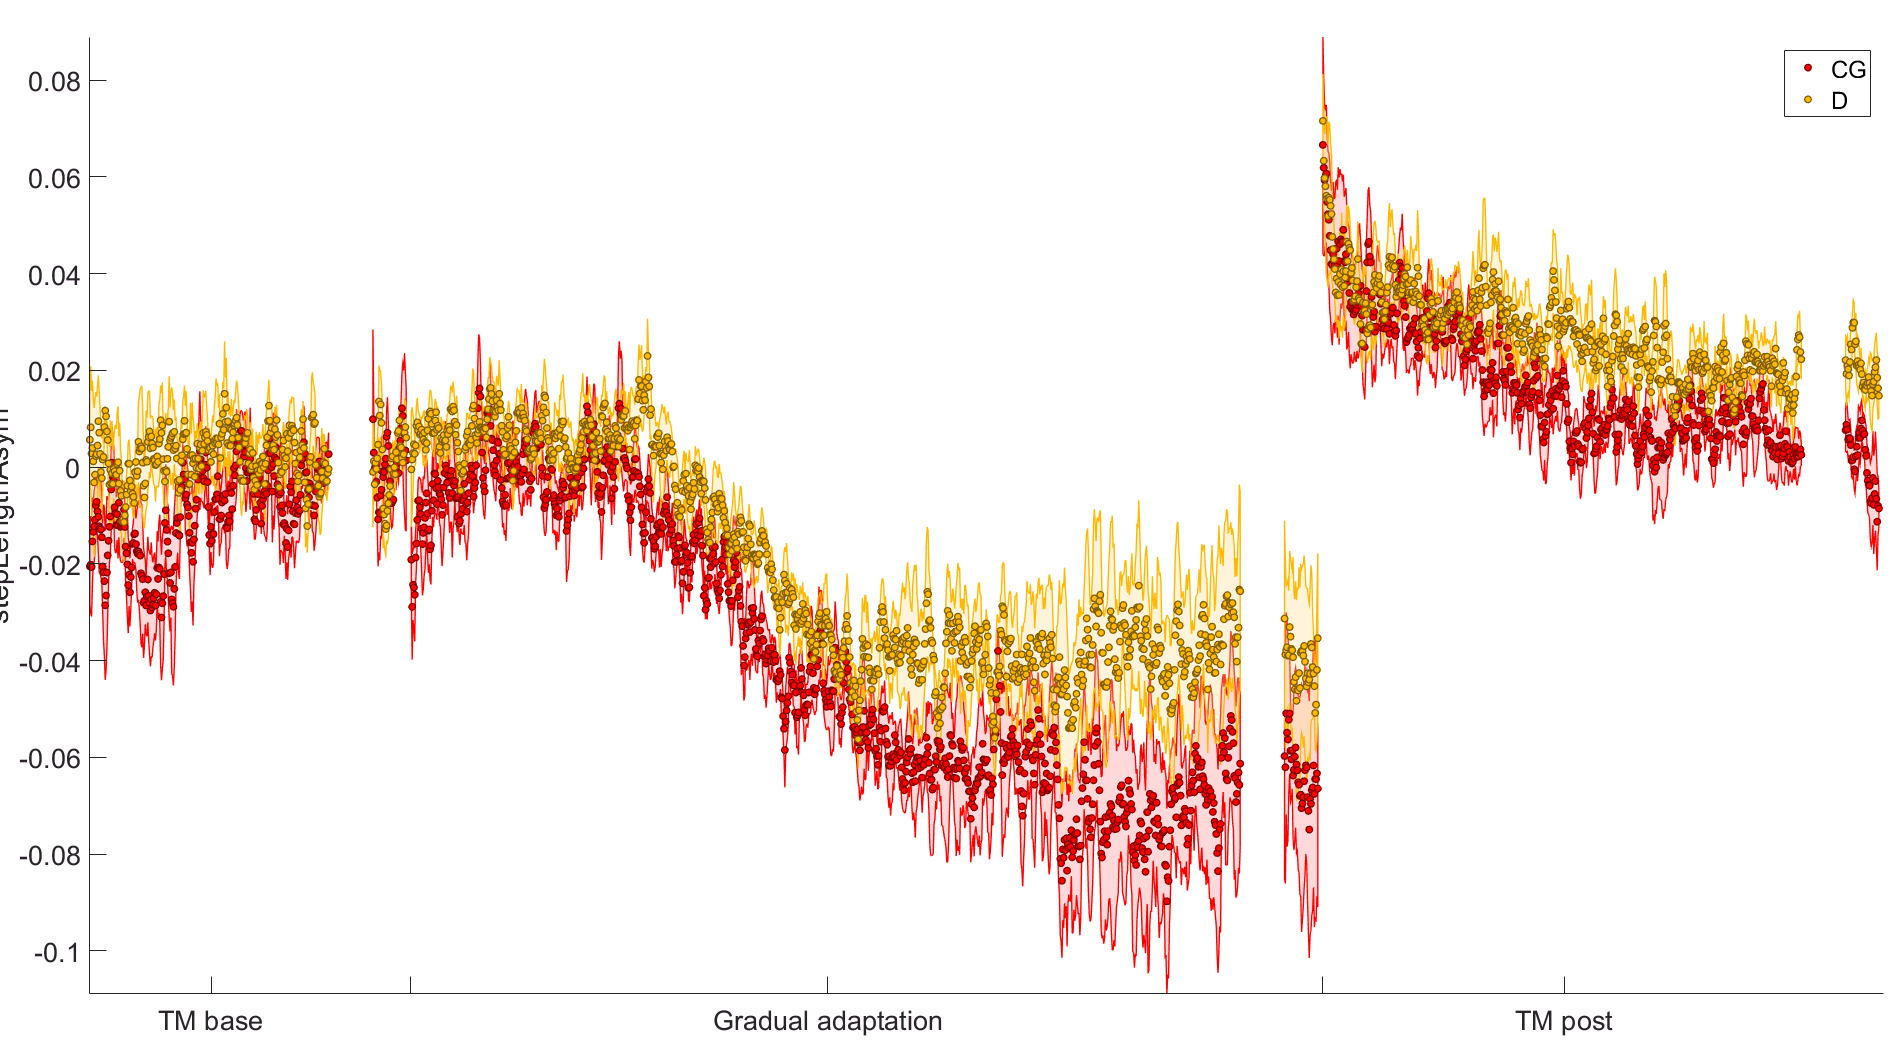


params={'stepLengthAsym'}; %you can plot which ever parameter you are interested on check into the adaptData.data for labels
binwidth=5; %Window of the running average
trialMarkerFlag=0; %1 if you want to separete the time course by trial 0 to separece by condition 
indivFlag=0; %0 to plot group mean 1 to plot indiv subjects
indivSubs=[]; %Use when you want to plot a specidfic subject in a group 
colorOrder=[]; %Let the function take care of this at least you wanted in a specific set of color then by my guess and add the list here
biofeedback= 0; % At least that you are providing with biofeedback to the subject
removeBiasFlag=1; %if you want to remove bias 
labels={'CG','D'}; %Groups names 
filterFlag=[];
plotHandles=[];
alignEnd=40; % # strides align at the end of the trial (PLAY with it as see what happens)
alignIni=0; %  # strides align at the beginning of the trial (PLAY with it as see what happens) 

adaptData=cellfun(@(x) x.adaptData,adaptDataGroups,'UniformOutput',false); %Notice that adaptDataGroups(1) decide that I only want to plot the CG group 
adaptationData.plotAvgTimeCourse(adaptData,params,conditions,binwidth,trialMarkerFlag,indivFlag,indivSubs,colorOrder,biofeedback,removeBiasFlag,labels,filterFlag,plotHandles,alignEnd,alignIni);

## Define epoch for bar plots 

Most of the time we are interested in specific epochs of the subjects behavior (Ex: Early adaptation, Steady State, Early post adaptation). A easy way to plot this bar plot is by using the defineEpoch function 

epochNames={'Initial','Last'};
condition= {'Gradual Adaptation','Gradual Adaptation'}; %Change conditions names to your own! 
strideNo=[5 -40]; %Positive vaues define inital; negative values define # strides at end of that condition
exemptFirst=5; %Number of strides you want to ignore at the beginning of the condition
exemptLast=5; %Number of strides you want to ignore at the end of the condition
summaryMethod={'nanmean'}; %Method to analyze bar plots 
shortName=[];

[epochs] = defineEpochs(epochNames,condition,strideNo,exemptFirst,exemptLast,summaryMethod,shortName);


## Bar plots

This is the function to plot the epochs that we define above

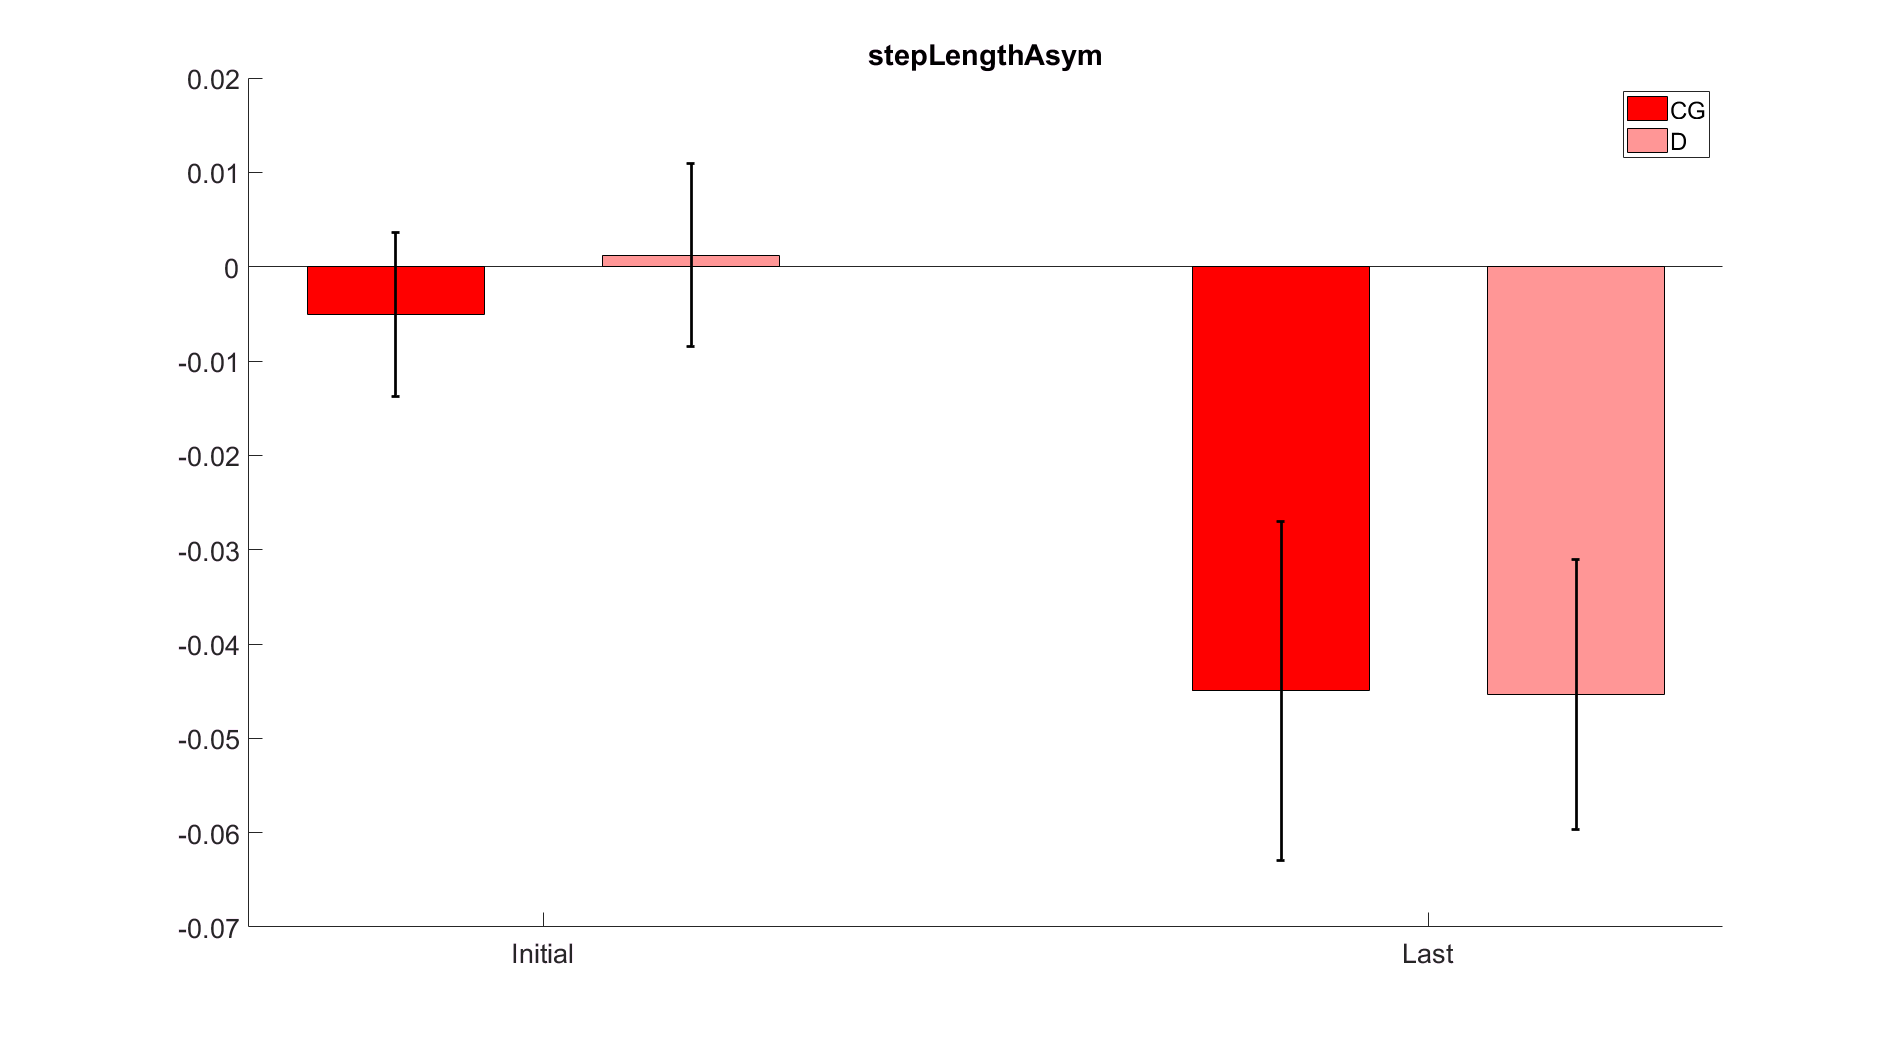

Current plot held


 CG=adaptationData.createGroupAdaptData({'CG07params','CG08params','CG09params','CG10params'});
 D=adaptationData.createGroupAdaptData({'D07params','D08params','D09params','D10params'});

adaptDataGroups{1}=CG;
adaptDataGroups{2}=D; %You can do this with as many groups you need 
params={'stepLengthAsym'};

[data,validStrides,everyStrideData]=getEpochData(adaptDataGroups{1},epochs,params,0); %This function output a matrix with the data from the epochs FYI

params={'stepLengthAsym'}; %you can plot which ever parameter you are interested on check into the adaptData.data for labels
indivFlag=0; %0 to plot group mean 1 to plot indiv subjects
labels={'CG','D'}; %Groups names 

biofeedback= 0; % At least that you are providing with biofeedback to the subject
p=subplot(1,1,1);
plotHandles=p;
colorOrder=[]; %Let the function take care of this at least you wanted in a specific set of color then by my guess and add the list here
medianFlag=[];
medianFlag=[];
significanceThreshold=[];
significancePlotMatrixGroups=[];
signifPlotMatrixConds=[];
removeBias=1;
if removeBias=1;
    adaptData=cellfun(@(x) x.adaptData,adaptDataGroups,'UniformOutput',false); %Notice that adaptDataGroups(1) decide that I only want to plot the CG group 
     adaptDataGroups= adaptData.removeBias;
end

[figHandle,allData]=groupAdaptationData.plotMultipleEpochBars(adaptDataGroups,params,epochs,indivFlag,labels,plotHandles,colorOrder,medianFlag,significanceThreshold,significancePlotMatrixGroups,signifPlotMatrixConds);

## Plot Group Time Course and Bar Plots Together 

params={'stepLengthAsym'}; %you can plot which ever parameter you are interested on check into the adaptData.data for labels
binwidth=5; %Window of the running average
trialMarkerFlag=0; %1 if you want to separete the time course by trial 0 to separece by condition 
indivFlag=0; %0 to plot group mean 1 to plot indiv subjects
indivSubs=[]; %Use when you want to plot a specidfic subject in a group 
colorOrder=[]; %Let the function take care of this at least you wanted in a specific set of color then by my guess and add the list here
biofeedback= 0; % At least that you are providing with biofeedback to the subject
labels={'CG','D'}; %Groups names 
medianFlag=[];

[fh,ph,allData]=adaptationData.plotGroupedTimeAndEpochBars(adaptDataGroups,params,epochs,binwidth,trialMarkerFlag,indivFlag,indivSubs,colorOrder,biofeedback,labels,medianFlag);

Current plot held
Current plot held


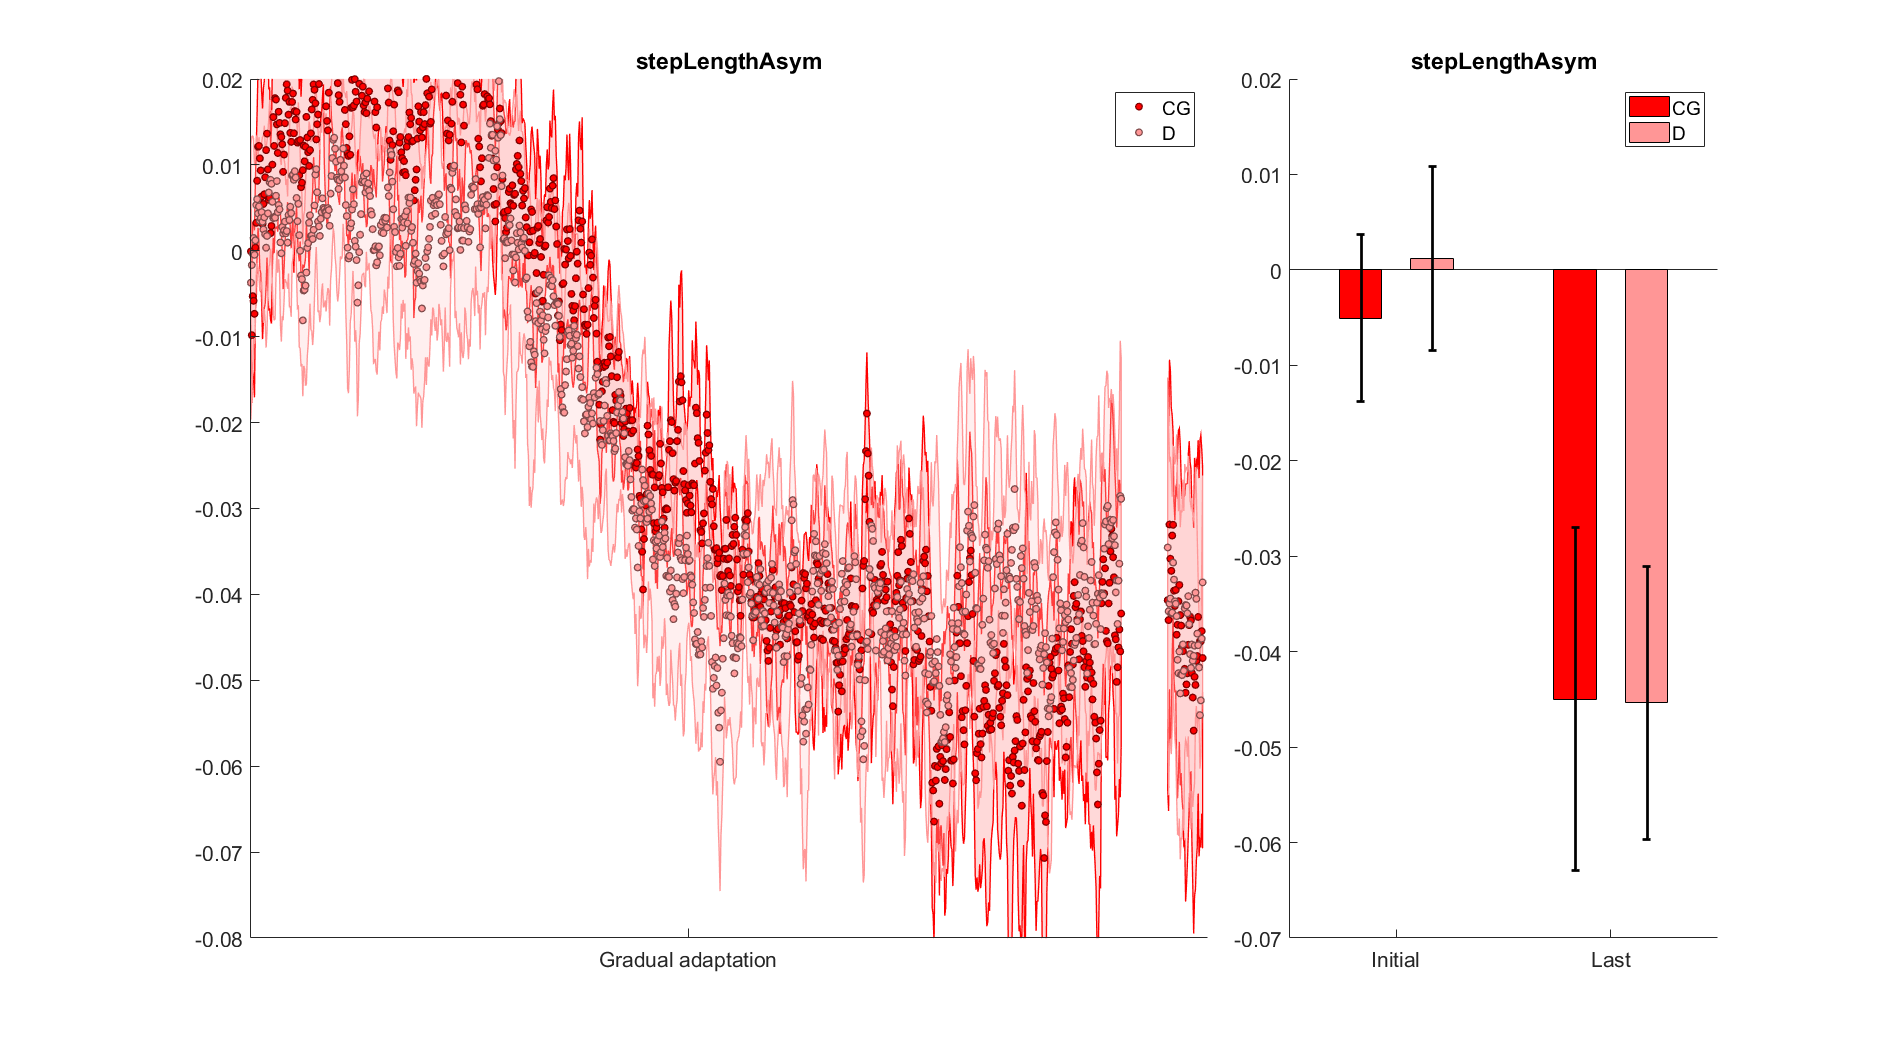

set(fh,'units','normalized','outerpos',[0 0 1 1.2]);